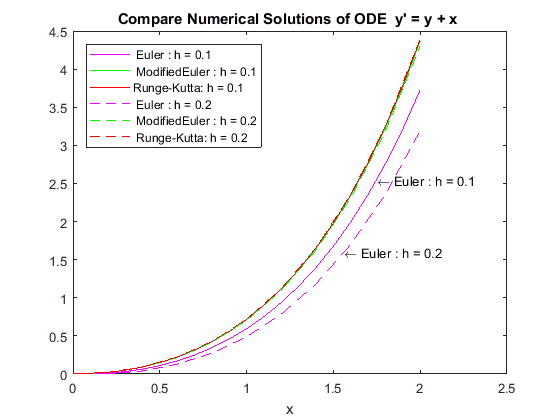

clear;
x=0;y=0;        %% Declare Initial Conditions
x_final=2;      %% Assuming I am expected to stop iteration at x=2
x0 = x; y0 = y;

h=0.1;                                         %% Plot for step size, h=0.1
[t1,data1] = eulerm(x,y,h,x_final);            %% Euler method
[t2,data2] = eulermimproved(x,y,h,x_final);    %% Modified Euler method
[t3,data3] = rungek(x,y,h,x_final);            %% Runge-Kutta method

h=0.2;                                         %% Plot for step size, h=0.2
[t4,data4] = eulerm(x,y,h,x_final);            %% Euler method
[t5,data5] = eulermimproved(x,y,h,x_final);    %% Modified Euler method
[t6,data6] = rungek(x,y,h,x_final);            %% Runge-Kutta method

plot(t1,data1,'color', 'm') ; hold on;text(1.75,2.55 ,'\leftarrow Euler : h = 0.1 '); 
plot(t2,data2,'color', 'g')
plot(t3,data3,'color', 'r')
plot(t4,data4,'m--');  text(1.56,1.6,'\leftarrow Euler : h = 0.2 '); 
plot(t5,data5,'g--')
plot(t6,data6,'r--'); hold off;
titlestr = "Compare Numerical Solutions of ODE  y' = y + x "; % + newline ; 
title(titlestr);xlabel('x');
legend(' Euler : h = 0.1', ' ModifiedEuler : h = 0.1', ...
    ...
     'Runge-Kutta: h = 0.1 ', ' Euler : h = 0.2', ...
     ...
     ' ModifiedEuler : h = 0.2', ' Runge-Kutta: h = 0.2 ', ...
     ...
      'Location','northwest') ;      

**Observable` effect of increasing the step size:** 

The value of y as a function of x changes with corresponding change in the value of step size, h from 

0.1 to 0.2 using Euler method. The value of y for the first-order differential equation, y' = x + y is 

inversely proportional to the change in value of the step size, h for euler method. Whereas the 

increase in value of the step size have no observable impact on the value of y as a function of x using 

Improved Euler and Runge-Kutta methods, even with, the values of y as a function of x for every were 

apparently the same for the two methods. All the four graphs for Modified euler and runge-kutta 

methods with same gradient. The two graphs of euler method have, different gradients. Modified Euler 

and Runge-kutta methods are better numerical solution for ordinary differential equations relative to 

Euler method. 

**Compare with Exact Solution**

      y = derivs2(y0);     

$$ode(x) = \frac{\partial }{\partial x}y\left(x\right)=x+y\left(x\right)$$

$$y = {\mathrm{e}}^{x}-x-1$$

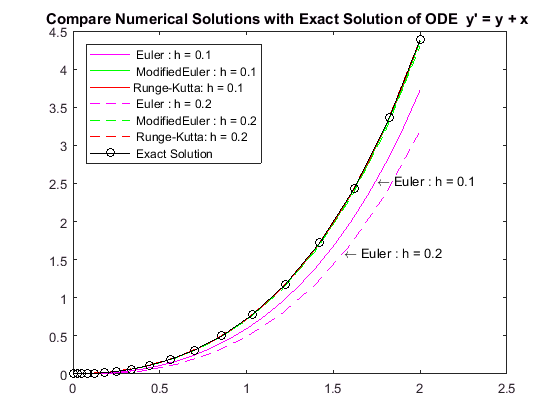

%subplot(2,2,[1 4])
xspan = [x0 x_final];                          %% The Plot for exact solution
[x,y] = ode23(@(x,y) x+y , xspan, y0);

plot(t1,data1,'color', 'm') ;hold on;
text(1.75,2.55 ,'\leftarrow Euler : h = 0.1 '); 
plot(t2,data2,'color', 'g')
plot(t3,data3,'color', 'r')
plot(t4,data4,'m--');text(1.56,1.6 ,'\leftarrow Euler : h = 0.2 '); 
plot(t5,data5,'g--')
plot(t6,data6,'r--')
plot(x,y, 'k-o')
titlestr = "Compare Numerical Solutions with Exact Solution of ODE " ...
    ...
    + " y' = y + x "; % + newline ; 
title(titlestr);
legend(' Euler : h = 0.1', ' ModifiedEuler : h = 0.1', ...
    ...
     'Runge-Kutta: h = 0.1 ', ' Euler : h = 0.2', ...
     ...
     ' ModifiedEuler : h = 0.2', ' Runge-Kutta: h = 0.2 ', ...
     ...
     ' Exact Solution', 'Location','northwest')



%subplot(x,y, '-o')

## Runge-Kutta 4th Order

function [t, data] = rungek(x,y,h,x_final)
    Nsteps = round(x_final/h);
    t = zeros(Nsteps,1);    data = zeros(Nsteps,1);
    
    t(1) = x; data(1,:) = y; %% store intial condition
    for i =1:Nsteps
        dy = derivs(x,y); k1 = h*dy;
        dy = derivs(x + h/2,y+k1/2); k2 = h*dy;
        dy = derivs(x + h/2,y+k2/2); k3 = h*dy;
        dy = derivs(x + h,y+k3); k4 = h*dy;
        k = (k1 + 2 * k2 + 2 * k3 + k4)/6;
        y = y + k; x = x + h;
        t(i+1) = x; data(i+1,:) = y ; 
    end
end

## Modified Euler Method

function [t, data] = eulermimproved(x,y,h,x_final)
    Nsteps = round(x_final/h);
    t = zeros(Nsteps,1);    data = zeros(Nsteps,1);
    
    t(1) = x; data(1,:) = y; %% store intial condition
    for i =1:Nsteps
        dy = derivs(x,y); k1 = h*dy;
        x = x + h;
        dy = derivs(x, y+k1); k2 = h*dy;
        y = y + (k1 + k2)./2;
        t(i+1) = x; data(i+1,:) = y ; 
   end
end

## Euler Method

function [t, data] = eulerm(x,y,h,x_final)
    Nsteps = round(x_final/h);
    t = zeros(Nsteps,1);    data = zeros(Nsteps,1);
    
    t(1) = x;data(1,:) = y;  %% store intial condition
    for i =1:Nsteps
        dy = derivs(x,y); y = y + h*dy;
        x = x + h;
        t(i+1) = x; data(i+1,:) = y ; 
    end
end

## **Solution to the differential equation**

function y = derivs2(y0) 
    syms y(x)
    dy = derivs(x,y);

    ode = diff(y) == dy
    cond = y(0) == y0;
    y = dsolve(ode,cond)
end

## The differential equation

function dy = derivs(x,y )
    dy = y + x ;
end